%Parameters
    eta     = 0.321;
    nu      = 0.273;
  sigma     = 0.314;
beta_asym   = 1.569;
 beta_sym   = 1.4;
 beta_sev   = 0.586;
gamma_asym  = 1.909;
 gamma_sym  = 0.857;
gamma_sev_r = 0.28;
gamma_sev_d = 2.146;
  epsilon   = 0.552;
  
      N     = 40000000;

I0 = 11;

S0 = N - I0;
E0 = 0;

I_asym0 = eta*I0;
I_sym0 = (1 - eta)*(1 - nu)*I0;
I_sev0 = (1 - eta)*nu*I0;

R0 = 0;
D0 = 0;

%Reading data

data = xlsread('COVID.xlsx');
n = fliplr(data(:, 1)');
cases = fliplr(data(:, 2)');

[n, X] = ode45(@F, n, [S0; E0; I_asym0; I_sym0; I_sev0; R0; D0]);

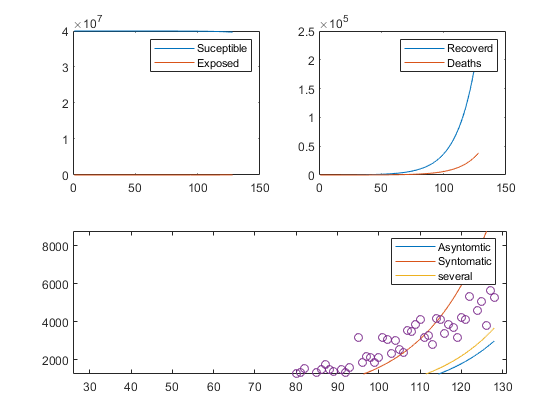

figure
subplot(2, 2, 1)
    plot(n, X(:, 1:2));
    legend('Suceptible', 'Exposed')
subplot(2, 2, 2)
    plot(n, X(:, 6:7));
    legend('Recoverd', 'Deaths')
subplot(2, 2, [3, 4])
    plot(n, X(:, 3:5));
    hold on
    plot(n, cases, 'o')
    legend('Asyntomtic', 'Syntomatic', 'several')

function dX = F(t, X)

%loading parameters
 eta = evalin('base', 'eta'); nu = evalin('base', 'nu'); sigma = evalin('base', 'sigma');
 beta_asym = evalin('base', 'beta_asym'); beta_sym = evalin('base', 'beta_sym'); beta_sev = evalin('base', 'beta_sev');
 gamma_asym = evalin('base', 'gamma_asym'); gamma_sym = evalin('base', 'gamma_sym');
 gamma_sev_r = evalin('base', 'gamma_sev_r'); gamma_sev_d = evalin('base', 'gamma_sev_d'); 
 epsilon = evalin('base', 'epsilon'); N = evalin('base', 'N');    
    
    S = X(1); E = X(2); I_asym = X(3); I_sym  = X(4);
    I_sev = X(5); R = X(6); D = X(7);
    
    dX = [-(beta_asym*I_asym + beta_sym*I_sym + beta_sev*I_sev).*S/N;...
        
           (beta_asym*I_asym + beta_sym*I_sym + beta_sev*I_sev).*S/N - epsilon*E;...
           
           eta*epsilon*E - gamma_asym*I_asym;...
           
           (1 - eta)*(1 - nu)*epsilon*E - gamma_sym*I_sym;...
           
           (1 - eta)*nu*epsilon*E - ((1 - sigma)*gamma_sev_r + sigma*gamma_sev_d)*I_sev;... %TODO: here
           
           gamma_asym*I_asym + gamma_sym*I_sym + (1 - sigma)*gamma_sev_r*I_sev;...
           
           sigma*gamma_sev_d*I_sev
           
           ];
end
